# Rail under weak chaotic shaking

 The system is shown pictorially :

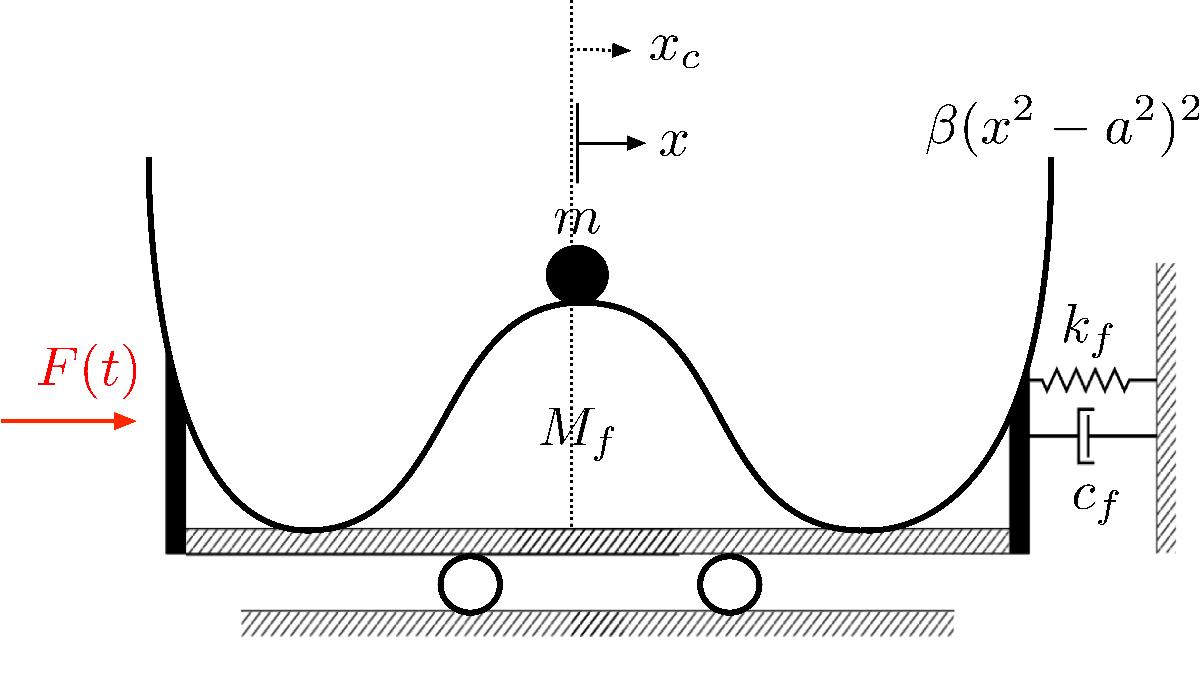

The system is described as : 


$$\mathbf{M}={\scriptscriptstyle \left(\begin{array}{cc}
M_{f}+m & 0\\
0 & \frac{mM_{f}}{m+M_{f}}
\end{array}\right)},\quad\mathbf{K}={\scriptstyle \left(\begin{array}{cc}
k_{f} & -k_{f}\frac{m}{M_{f}+m}\\
-k_{f}\frac{m}{M_{f}+m} & -4\beta a^{2}mg+k_{f}\frac{m^{2}}{(M_{f}+m)^{2}}
\end{array}\right)},$$


$\mathbf{C}={\scriptstyle \left(\begin{array}{cc}
c_{f} & -c_{f}\frac{m}{M_{f}+m}\\
-c_{f}\frac{m}{M_{f}+m} & c+c_{f}\frac{m^{2}}{(M_{f}+m)^{2}}
\end{array}\right)},\quad\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})={\scriptstyle \left(\begin{array}{c}
0\\
4g\beta mx^{3}+16m\beta^{2}a^{4}x\dot{{x}}^{2}
\end{array}\right)},$ and 


$$\mathbf{F}(t)={\scriptscriptstyle \left(\begin{array}{c}
(m+M_{f})g(t)\\
0
\end{array}\right)}.$$


The signal $g(t)$ is generated using the initial condition $[0,0.3,0.5]$. The system paramters and forcing are generated below: 

clear all
c = 0.3;
k = 1;
a = 0.3;
g = 9.8;
m = 1;
M = 4;
cf = 0.3;
scale = 5*a^3;%2*a^3;
K = [a^2*(1 + m/M)*g*4/scale - k*m/(M*(m + M)), k/M; k*m/(M + m)^2, -k/(M + m)];
Cd = [-cf*(M + m)/(M*m) - c*m/((M + m)*M), c/M; c*m/(m + M)^2, -c/(M + m)];

A = [zeros(2),eye(2);K,Cd];


B = eye(4);

% quadratic part
F2 = sptensor([4 4 4]);
F3 = sptensor([4 4 4 4]);
F3(3,1,1,1) = -4*g*(1+m/M)/scale;
F3(3,1,3,3) = -16*(1+m/M)*a^4/scale^2;

F = {F2,F3};

DS = DynamicalSystem();
set(DS,'A',A,'B',B,'fnl',F); 
set(DS.Options,'notation','tensor')
% spectrum analysis
[V,D,W] = DS.linear_spectral_analysis();


 The first 4 nonzero eigenvalues are given as 
   5.5196 + 0.0000i
  -0.0301 + 0.4465i
  -0.0301 - 0.4465i
  -5.9094 + 0.0000i



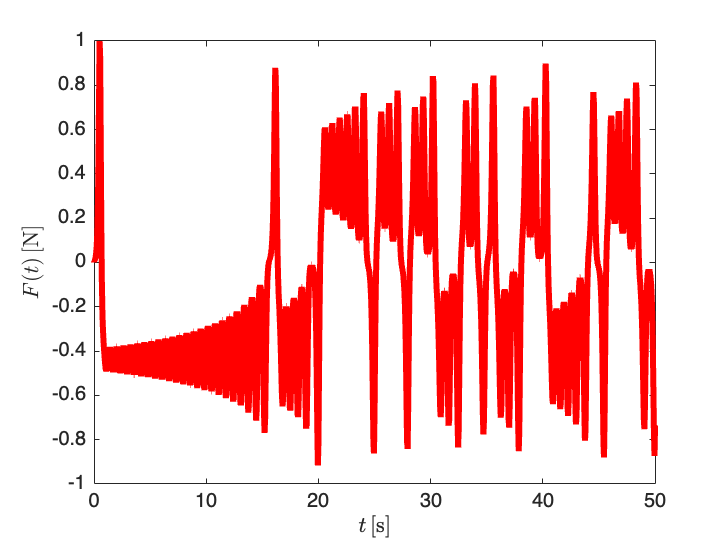

%%
% DS set up - SSM tool

A = V*diag(D)*inv(V);
VI = inv(V);

V_new = [V(:,4),V(:,1),V(:,2),V(:,3)];
D_new = [D(4),D(1),D(2),D(3)];
VI_new = inv(V_new);
A = V_new*diag(D_new)*VI_new;

%Lorenz force 

L = 0;
N_Max = 10000;
tspan = linspace(L,500,N_Max);


loren = @(t,y) lorenz_3D(t,y);
IC = [0;0.3;0.5];
[tk,yy] = ode45(loren,tspan,IC);

sigma = 10;
rho = 28;
beta = 8/3;


F_a_new = yy(:,1)/max(abs(yy(:,1)));


Force_Lorenz = griddedInterpolant(tspan(:),F_a_new(:),'spline');



plot(tk,F_a_new,'-','LineWidth',3,'Color','red')
xlabel('$t \,[$s$]$','Interpreter','latex');
ylabel('$F(t) \,[$N$]$','Interpreter','latex');
axis([0 50 -1 1])

The anchor trajectory is calculated to O(3). The non-zero anchor trajectory at various orders are saved. If you wish to recompute these please set flag to 1. 

flag =0;
% order epsilon solution
% AP = [0,0,1,0;0,0,0,1;-2*k,k,-c,c;k,-2*k,c,-2*c];
if flag == 1

% order epsilon solution -unstable


% order epsilon solution -unstable
% AP = [0,0,1,0;0,0,0,1;-2*k,k,-c,c;k,-2*k,c,-2*c];

xs_neg=@(t,ta) real(V*([zeros(1,max(size(ta)));(exp(D(2)*(t-ta)));exp(D(3)*(t-ta));(exp(D(4)*(t-ta)))].*(inv(V)*[0*ones(1,max(size(ta)));0*ones(1,max(size(ta)));0*ones(1,max(size(ta)));Force_Lorenz(ta)])));
xs_pos=@(t,ta) real(V*([exp(D(1)*(t-ta));zeros(1,max(size(ta)));zeros(1,max(size(ta)));zeros(1,max(size(ta)))].*(inv(V)*[0*ones(1,max(size(ta)));0*ones(1,max(size(ta)));0*ones(1,max(size(ta)));Force_Lorenz(ta)])));
% 
neg_L =1;


% 
% 
tcalc = tspan;
N_Max = max(size(tcalc));
LT = [];
start_time = 1;
xi_sol = cell(1,max(size(start_time)));

tic
sol_1 = [];
parfor i = 1:max(size(tcalc))
Lo_neg = neg_L - 1 + i ;
T_neg = tspan(start_time(1):Lo_neg);
T_pos = tspan(Lo_neg:end);

ti = tcalc(i);

INx_neg = xs_neg(ti,T_neg);
INx_pos = xs_pos(ti,T_pos);

Q1x_neg = trapz(T_neg,INx_neg,2);
Q1x_pos = trapz(T_pos,INx_pos,2);

sol_1  =[sol_1,Q1x_neg-Q1x_pos];
end    
xi_sol{1,1} = sol_1;
LT = [LT,tspan(start_time(1))];
toc

xi_solg=sol_1.'; 
xi_full = griddedInterpolant(tcalc(:),xi_solg,'spline');
xi_full_eval = @(xa) xi_full(xa);
save('Order_Ep_1_mixed_unstable.mat','xi_full_eval')

xi_sol0=xi_sol{1,1};
xi_sol1 = griddedInterpolant(tcalc(:),(xi_sol0(1,:)).','spline');
xi_sol2 = @(xq) interp1(tcalc(:),(xi_sol0(2,:)).',xq,'spline');
xi_sol3 = griddedInterpolant(tcalc(:),(xi_sol0(3,:)).','spline');
xi_sol4 = @(xq) interp1(tcalc(:),(xi_sol0(4,:)).',xq,'spline');
xi_net_sol = @(t) [xi_sol1(t);xi_sol2(t);xi_sol3(t);xi_sol4(t)];
save('Order_Ep_1_mixed_unstable13.mat','xi_sol1','xi_sol3')

load('Order_Ep_1_mixed_unstable.mat','xi_full_eval')
load('Order_Ep_1_mixed_unstable13.mat','xi_sol1','xi_sol3')

start_time = neg_L;


xs_neg=@(t,ta) real(V*([zeros(1,max(size(ta)));(exp(D(2)*(t-ta)));exp(D(3)*(t-ta));(exp(D(4)*(t-ta)))].*(inv(V)*[0*ones(1,max(size(ta)));0*ones(1,max(size(ta)));(-4*g*(1+m/M)*xi_sol1(ta).^3/scale-16*(1+m/M)*a^4.*xi_sol1(ta).*xi_sol3(ta).^2/scale^2);0*ones(1,max(size(ta)))])));
xs_pos=@(t,ta) real(V*([exp(D(1)*(t-ta));zeros(1,max(size(ta)));zeros(1,max(size(ta)));zeros(1,max(size(ta)))].*(inv(V)*[0*ones(1,max(size(ta)));0*ones(1,max(size(ta)));(-4*g*(1+m/M)*xi_sol1(ta).^3/scale-16*(1+m/M)*a^4.*xi_sol1(ta).*xi_sol3(ta).^2/scale^2);0*ones(1,max(size(ta)))])));




N_Max = max(size(tcalc));
LT = [];

xi3 = cell(1,max(size(start_time)));

tic
sol_1 = [];
parfor i = 1:max(size(tcalc))
Lo_neg = neg_L - 1 + i ;
T_neg = tspan(start_time:Lo_neg);
T_pos = tspan(Lo_neg:end);

ti = tcalc(i);

INx_neg = xs_neg(ti,T_neg);
INx_pos = xs_pos(ti,T_pos);

Q1x_neg = trapz(T_neg,INx_neg,2);
Q1x_pos = trapz(T_pos,INx_pos,2);

sol_1  =[sol_1,Q1x_neg-Q1x_pos];
end    
xi3{1,1} = sol_1;
LT = [LT,tspan(start_time(1))];
toc

xi_solg=sol_1.'; 
xi_full = griddedInterpolant(tcalc(:),xi_solg,'spline');
xi_full_eval3 = @(xa) xi_full(xa);
save('Order_Ep_3_mixed_unstable.mat','xi_full_eval3')

end


Now we calculate the non-autonomous SSM coefficients upto this order by solving the invariance PDE. 

l1 = D_new(1);
l2 = D_new(2);
l3 = D_new(3);
Sc = scale;
P = V_new;
PI = VI_new;

if flag == 1

P = V_new;
PI = VI_new;

Sc = scale;

h300 = (+ (4.*g.*P(1, 1).^3.*PI(3, 3))./Sc + (4.*g.*m.*P(1, 1).^3.*PI(3, 3))./(M.*Sc) + (16.*a.^4.* ...
P(1, 1).*P(3, 1).^2.*PI(3, 3))./Sc.^2 + ...
   (16.*a.^4.*m.*P(1, 1).*P(3, 1).^2.*PI(3, 3))./(M.*Sc.^2))./(l3-3.*l1);

h210 = (+ (12.*g.*P(1, 1).^2.*P(1, 2).*PI(3, 3))./Sc + ...
   (12.*g.*m.*P(1, 1).^2.*P(1, 2).*PI(3, 3))./(M.*Sc) + (16.*a.^4.*P(1, 2).*P(3, 1).^2.*PI(3, 3))./Sc.^2 + (16.*a.^4.*m.*P(1, 2).*P(3, 1).^2.*PI(3, 3))./(M.*Sc.^2) + ...
   (32.*a.^4.*P(1, 1).*P(3, 1).*P(3, 2).*PI(3, 3))./Sc.^2 + (32.*a.^4.*m.*P(1, 1).*P(3, 1).*P(3, 2).* ...
PI(3, 3))./(M.*Sc.^2))./(l3-2.*l1-l2);

h120 = (+ (12.*g.*P(1, 1).*P(1, 2).^2.*PI(3, 3))./Sc + (12.*g.*m.*P(1, 1).*P(1, 2).^2.*PI(3, 3))./(M.*Sc) + ...
   (32.*a.^4.*P(1, 2).*P(3, 1).*P(3, 2).*PI(3, 3))./Sc.^2 + (32.*a.^4.*m.*P(1, 2).*P(3, 1).*P(3, 2).* ...
PI(3, 3))./(M.*Sc.^2) + (16.*a.^4.*P(1, 1).*P(3, 2).^2.*PI(3, 3))./Sc.^2 + ...
   (16.*a.^4.*m.*P(1, 1).*P(3, 2).^2.*PI(3, 3))./(M.*Sc.^2))./(l3-2.*l2-l1);

h030 = (+ (4.*g.*P(1, 2).^3.*PI(3, 3))./Sc + (4.*g.*m.*P(1, 2).^3.*PI(3, 3))./(M.*Sc) + ...
   (16.*a.^4.*P(1, 2).*P(3, 2).^2.*PI(3, 3))./Sc.^2 + (16.*a.^4.*m.*P(1, 2).*P(3, 2).^2.* ...
PI(3, 3))./(M.*Sc.^2))./(l3-3.*l2);


hc030 = conj(h300);
hc300 = conj(h030);
hc210 = conj(h120);
hc120 = conj(h210);


% 
% 
% h_coeff_pos=@(t,ta) [exp((l3-l2-l1)*(t-ta)).*-1.*((0.0045528085943358785 - 0.03294435888281321*1i).* xi_sol1(ta) + (0.00004266803042538553 - 0.00030874807891231816*1i).* ...
% xi_sol3(ta)) ;
% exp((l3-2*l1)*(t-ta)).*-1.*((0.003062413331418653 - 0.022159781538649215*1i).*xi_sol1(ta) - ...
% (0.0007454913958689365 - 0.0053944143665758835*1i).*xi_sol3(ta)) ;
%  exp((l3-l1)*(t-ta)) ...
% .*-1.*(- (0.0027660226580715234 - 0.020015083269450215*1i).* xi_sol1(ta).^2 + (0.005414753303779644 - 0.0391814354602*1i).* xi_sol1(ta).* xi_sol3(ta) - (0.0003763296133430644 - 0.00272314058087758*1i).*xi_sol3(ta).^2) ;
% ];

h_coeff_pos=@(t,ta) [exp((l3-l2-l1).*(t-ta)).*-1.*( + (24.*g.*P(1, 1).*P(1, 2).*(xi_sol1(ta)).*PI(3, 3))./Sc + ...
   (24.*g.*m.*P(1, 1).*P(1, 2).*(xi_sol1(ta)).*PI(3, 3))./(M.*Sc) + (32.*a.^4.*P(3, 1).* ...
P(3, 2).*(xi_sol1(ta)).*PI(3, 3))./Sc.^2 + (32.*a.^4.*m.*P(3, 1).*P(3, 2).*(xi_sol1(ta)).*PI(3, 3))./(M.*Sc.^2) + ...
   (32.*a.^4.*P(1, 2).*P(3, 1).*(xi_sol3(ta)).*PI(3, 3))./Sc.^2 + (32.*a.^4.*m.*P(1, 2).* ...
P(3, 1).*(xi_sol3(ta)).*PI(3, 3))./(M.*Sc.^2) + (32.*a.^4.*P(1, 1).*P(3, 2).*(xi_sol3(ta)).*PI(3, 3))./Sc.^2 + ...
   (32.*a.^4.*m.*P(1, 1).*P(3, 2).*(xi_sol3(ta)).*PI(3, 3))./(M.*Sc.^2)) ;

exp((l3-2.*l1).*(t-ta)).*-1.*(+ (12.*g.*P(1, 1).^2.*(xi_sol1(ta)).*PI(3, 3))./Sc + (12.*g.*m.* ...
P(1, 1).^2.*(xi_sol1(ta)).*PI(3, 3))./(M.*Sc) + ...
   (16.*a.^4.*P(3, 1).^2.*(xi_sol1(ta)).*PI(3, 3))./Sc.^2 + (16.*a.^4.*m.*P(3, 1).^2.*(xi_sol1(ta)).* ...
PI(3, 3))./(M.*Sc.^2) + (32.*a.^4.*P(1, 1).*P(3, 1).*(xi_sol3(ta)).*PI(3, 3))./Sc.^2 + ...
   (32.*a.^4.*m.*P(1, 1).*P(3, 1).*(xi_sol3(ta)).*PI(3, 3))./(M.*Sc.^2));


exp((l3-l1).*(t-ta)).*-1.*(+ (12.*g.*P(1, 1).*(xi_sol1(ta)).^2.*PI(3, 3))./Sc + (12.*g.*m.* ...
P(1, 1).*(xi_sol1(ta)).^2.*PI(3, 3))./(M.*Sc) + ...
   (32.*a.^4.*P(3, 1).*(xi_sol1(ta)).*(xi_sol3(ta)).*PI(3, 3))./Sc.^2 + (32.*a.^4.*m.* ...
P(3, 1).*(xi_sol1(ta)).*(xi_sol3(ta)).*PI(3, 3))./(M.*Sc.^2) + (16.*a.^4.*P(1, 1).*(xi_sol3(ta)).^2.*PI(3, 3))./Sc.^2 + ...
   (16.*a.^4.*m.*P(1, 1).*(xi_sol3(ta)).^2.*PI(3, 3))./(M.*Sc.^2))];

% h111 exp((l3-l2-l1)*(t-ta)).*(0.0008043804376629333 - 0.00582053852420905*1i).*xi_sol1(ta)
% h201 -1.*exp((l3-2*l1)*(t-ta)).*(0.0003808199518400002 - 0.00275563290289885*1i).*xi_sol1(ta)
% h102 exp((l3-l1)*(t-ta)).*(0.002766022658071523 - 0.02001508326945021*1i).*xi_sol1(ta).^2

% h021 -1.*exp((l3-2*l2)*(t-ta)).*(0.00042475970952190155 - 0.0030735832661311887*1i).*xi_sol1(ta)
% h012 -1.*exp((l3-l2)*(t-ta)).*(0.0029212420535412995 - 0.02113825885743593*1i).*xi_sol1(ta).^2

% h_coeff_neg=@(t,ta) [exp((l3-2*l2)*(t-ta)).*-1.*((0.0031003587156133655 - 0.022434356304742407*1i).*xi_sol1(ta) + (0.0007864452553481337 - 0.005690758615705421*1i).* ...
% xi_sol3(ta)) ;
% exp((l3-l2)*(t-ta)) ...
% .*-1.*(+(0.0029212420535412995- 0.02113825885743593*1i).*...
% xi_sol1(ta).^2 + (0.005408697909029281- 0.03913761831003883*1i).* xi_sol1(ta) .*xi_sol3(ta) + (0.0003974478984409931 - 0.0028759535860457047*1i ).* xi_sol3(ta).^2)
% ];


h_coeff_neg=@(t,ta) [ exp((l3-2.*l2).*(t-ta)).*-1.*(+ (12.*g.*P(1, 2).^2.*(xi_sol1(ta)).*PI(3, 3))./Sc + ...
   (12.*g.*m.*P(1, 2).^2.*(xi_sol1(ta)).*PI(3, 3))./(M.*Sc) + (16.*a.^4.*P(3, 2).^2.*(xi_sol1(ta)).*PI(3, 3))./Sc.^2 + (16.*a.^4.*m.*P(3, 2).^2.*(xi_sol1(ta)).*PI(3, 3))./(M.*Sc.^2) + ...
   (32.*a.^4.*P(1, 2).*P(3, 2).*(xi_sol3(ta)).*PI(3, 3))./Sc.^2 + (32.*a.^4.*m.*P(1, 2).* ...
P(3, 2).*(xi_sol3(ta)).*PI(3, 3))./(M.*Sc.^2)) ;

   exp((l3-l2).*(t-ta)).*-1.*(+ (12.*g.*P(1, 2).*(xi_sol1(ta)).^2.*PI(3, 3))./Sc + ...
   (12.*g.*m.*P(1, 2).*(xi_sol1(ta)).^2.*PI(3, 3))./(M.*Sc) + (32.*a.^4.*P(3, 2).*(xi_sol1(ta)).*(xi_sol3(ta)).* ...
PI(3, 3))./Sc.^2 + (32.*a.^4.*m.*P(3, 2).*(xi_sol1(ta)).*(xi_sol3(ta)).*PI(3, 3))./(M.*Sc.^2) +  ...
   (16.*a.^4.*P(1, 2).*(xi_sol3(ta)).^2.*PI(3, 3))./Sc.^2 + (16.*a.^4.*m.*P(1, 2).*(xi_sol3(ta)).^2.* ...
PI(3, 3))./(M.*Sc.^2))];

N_Max = max(size(tcalc));
sol_1r_neg = [];
sol_1i_neg = [];

sol_1r_pos = [];
sol_1i_pos = [];

tic
parfor i = 1:max(size(tcalc))
Lo = neg_L - 1 + i ;
T_neg = tspan(1:Lo);
T_pos = tspan(Lo:end);
ti = tcalc(i);

INx_neg = h_coeff_neg(ti,T_neg);
INxr_neg = real(INx_neg);
INxi_neg = imag(INx_neg);
Q1xr_neg = trapz(T_neg,INxr_neg,2);
Q1xi_neg = trapz(T_neg,INxi_neg,2);
sol_1r_neg  =[sol_1r_neg,Q1xr_neg];
sol_1i_neg  =[sol_1i_neg,Q1xi_neg];

INx_pos = h_coeff_pos(ti,T_pos);
INxr_pos = real(INx_pos);
INxi_pos = imag(INx_pos);
Q1xr_pos = trapz(T_pos,INxr_pos,2);
Q1xi_pos = trapz(T_pos,INxi_pos,2);
sol_1r_pos  =[sol_1r_pos,-1*Q1xr_pos];
sol_1i_pos  =[sol_1i_pos,-1*Q1xi_pos];

end    
toc

h111r = griddedInterpolant(tcalc(:),(sol_1r_pos(1,:)).','spline');
h111i = griddedInterpolant(tcalc(:),(sol_1i_pos(1,:)).','spline');
h111 = @(xa) h111r(xa) + 1i*h111i(xa);

h201r = griddedInterpolant(tcalc(:),(sol_1r_pos(2,:)).','spline');
h201i = griddedInterpolant(tcalc(:),(sol_1i_pos(2,:)).','spline');
h201 = @(xa) h201r(xa) + 1i*h201i(xa);

h102r = griddedInterpolant(tcalc(:),(sol_1r_pos(3,:)).','spline');
h102i = griddedInterpolant(tcalc(:),(sol_1i_pos(3,:)).','spline');
h102 = @(xa) h102r(xa) + 1i*h102i(xa);

h021r = griddedInterpolant(tcalc(:),(sol_1r_neg(1,:)).','spline');
h021i = griddedInterpolant(tcalc(:),(sol_1i_neg(1,:)).','spline');
h021 = @(xa) h021r(xa) + 1i*h021i(xa);

h012r = griddedInterpolant(tcalc(:),(sol_1r_neg(2,:)).','spline');
h012i = griddedInterpolant(tcalc(:),(sol_1i_neg(2,:)).','spline');
h012 = @(xa) h012r(xa) + 1i*h012i(xa);

%%

save('Mixed_Mode_Coeff_SSM.mat','h030','h300','h120','h210','h111','h201','h021','h012','h102')
load('Mixed_Mode_Coeff_SSM.mat','h030','h300','h120','h210','h111','h201','h021','h012','h102')
end
load('Mixed_Mode_Coeff_SSM.mat','h030','h300','h120','h210','h111','h201','h021','h012','h102')

load('Order_Ep_1_mixed_unstable13.mat','xi_sol1','xi_sol3')

load('Order_Ep_1_mixed_unstable.mat','xi_full_eval')

% 
load('Order_Ep_3_mixed_unstable.mat','xi_full_eval3')
% 
Ma1 = load('Mixed_Mode_Stable_plus_a.mat','XI_hyperbolic_solution');
XI_hyperbolic_solution_a1 = Ma1.('XI_hyperbolic_solution');

Ma1 = load('Mixed_Mode_Stable_minus_a.mat','XI_hyperbolic_solution');
XI_hyperbolic_solution_a2 = Ma1.('XI_hyperbolic_solution');
% 
XI_hyperbolic_solution = cell(1,3);
XI_hyperbolic_solution{1,1} = @(xa) xi_full_eval(xa);
XI_hyperbolic_solution{1,2} = {};
XI_hyperbolic_solution{1,3} = @(xa) xi_full_eval3(xa);

We also compute the anchor responses for pertubed stable fixed points.

Full order model and reduced order model comparison for various initial conditions launched at different initial times:


fig = figure

fig =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 460 560 420]
       Units: 'pixels'

  Show all properties


fontsize(fig, 20, "points")
set(gcf,'color','w');
box on
grid on ;
axis([0,150,-0.5,1])
ax1 = gca;
ax2 = axes( 'Position' ,[.2 .7 .35 .2]); 
box on
grid on ;
axis([0,400,0.278,0.322])
ax3 = axes( 'Position' ,[.65 .7 .2 .2]); 
box on
grid on ;
axis([60,62,-0.45,0.45])

NMTET = [];

b = 0.3;
z0 = [ b+1i*0, ...
       -b+1i*0, ...
       b+1i*-b, ...
       b+1i*b,...
       -b+1i*-b,...
       -b+b*1i,...
       0+1i*b,...
       0+1i*-b,...
       2*b+1i*0, ...
       -2*b+1i*0,...
       2*b+1i*-2*b,...
       2*b+1i*2*b,...
       -2*b+1i*-2*b,...
       -2*b+2*b*1i,...
       0+1i*2*b,...
       0+1i*-2*b
    ];

epsilon = 1;
ctspan = linspace(0,500,80000);
Unstable_Solution = epsilon*xi_full_eval(ctspan) + epsilon^3*xi_full_eval3(ctspan);

Stable_solution1 = epsilon*XI_hyperbolic_solution_a1{1,1}(ctspan) + epsilon^2*XI_hyperbolic_solution_a1{1,2}(ctspan) + epsilon^3*XI_hyperbolic_solution_a1{1,3}(ctspan);
Stable_solution2 = epsilon*XI_hyperbolic_solution_a2{1,1}(ctspan) + epsilon^2*XI_hyperbolic_solution_a2{1,2}(ctspan) + epsilon^3*XI_hyperbolic_solution_a2{1,3}(ctspan);
Stable_solution1(:,1) = Stable_solution1(:,1)+a;
Stable_solution1(:,2) = Stable_solution1(:,2)+a*m/(M+m);

Stable_solution2(:,1) = Stable_solution2(:,1)-a;
Stable_solution2(:,2) = Stable_solution2(:,2)-a*m/(M+m);




to1=find(ctspan>=20);
to2=find(ctspan>=40);
to3=find(ctspan>=60);

to = [1,to1(1),to2(1),to3(1)];



store_Traj = cell(5,4);
store_Traj(1,:) = {ctspan,Unstable_Solution.',Stable_solution1.',Stable_solution2.'};
for indk = 1:4
Yrec = [];
FullTra = [];
    for ind = 1:16



stop_index = find(ctspan>=1.5);

ctspanR = ctspan(to(indk):to(indk)+stop_index(1));
ctspanF = ctspan(to(indk):end);

u0 = [real(z0(ind));imag(z0(ind))];

[y0,modal0] = compute_SSM_phy(XI_hyperbolic_solution,ctspanR(1),V_new,VI_new,u0,h030,h300,h120,h210,h111,h201,h021,h012,h102,epsilon);

RomH = @(t,uk) rom_temp_model_noscale(t,uk,l1,l2,V_new,VI_new,epsilon,xi_sol1,xi_sol3,h300,h030,h120,h210,Sc,a,g,m,M);
tic
IC = u0;
[tred,ROM_SOL] = ode45(RomH,ctspanR,IC);
toc

[y_sol,modal_sol] = compute_SSM_phy(XI_hyperbolic_solution,tred.',V_new,VI_new,ROM_SOL.',h030,h300,h120,h210,h111,h201,h021,h012,h102,epsilon);

GH = @(t,y) Full_Order_Model_PM_vec(t,y,Force_Lorenz,epsilon,c,k,a,g,m,M,cf,Sc);
tic
IC = y0;
[tSP,Full_Traj] = ode45(GH,ctspanF,IC);
toc


% NMTE = sum(sqrt(sum((y_sol.' - Full_Traj).^2,2)))/(sqrt(max(sum((Full_Traj).^2,2)))*max(size(ctspan)))

hold(ax1, 'on' );
indexR=1;
fp1 = plot(ax1,ctspanF,Full_Traj(:,indexR),'-','LineWidth',3,'color',[0,0,0]);
hold on 
fp2 = plot(ax1,ctspanR,y_sol(indexR,:),'--','LineWidth',3,'color',[0,1,0]);
hold on
xlabel(ax1,'$t \,[$s$]$','Interpreter','latex');
ylabel(ax1,'$x \,[$m$]$','Interpreter','latex');
title_string = strcat('max$(|F_{ext}|) = ',num2str(epsilon*(M+m)),'$ [$\mathbf{N}$], expansion order $N = 3$');
title(ax1,title_string,'Interpreter','latex')

hold on

grid on ;


hold(ax2, 'on' );
hold on 
plot(ax2,ctspanF,Full_Traj(:,indexR),'-','LineWidth',3,'color',[0,0,0]);
hold on 
plot(ax2,ctspanR,y_sol(indexR,:),'--','LineWidth',3,'color',[0,1,0]);
hold on
% xlabel(ax2,'$t \,[$s$]$','Interpreter','latex');
% ylabel(ax2,'$x \,[$m$]$','Interpreter','latex');


grid on ;

hold(ax3, 'on' );
hold on 
plot(ax3,ctspanF,Full_Traj(:,indexR),'-','LineWidth',3,'color',[0,0,0]);
hold on 
plot(ax3,ctspanR,y_sol(indexR,:),'--','LineWidth',3,'color',[0,1,0]);
hold on
% xlabel(ax3,'$t \,[$s$]$','Interpreter','latex');
% ylabel(ax3,'$x \,[$m$]$','Interpreter','latex');

% axis([0,0.8,-1.2,1.2])
grid on ;


% Yrec = [Yrec;modal_sol];
% FullTra = [FullTra;VI_new*Full_Traj.'];

Yrec = [Yrec;y_sol];
FullTra = [FullTra;Full_Traj.'];


    end
    store_Traj(indk+1,:) = {ctspanR,Yrec,tSP,FullTra};
end

Elapsed time is 0.156456 seconds.


Elapsed time is 0.778227 seconds.


Elapsed time is 0.059501 seconds.


Elapsed time is 0.774619 seconds.


Elapsed time is 0.061782 seconds.


Elapsed time is 0.786864 seconds.


Elapsed time is 0.043745 seconds.


Elapsed time is 0.742595 seconds.


Elapsed time is 0.039984 seconds.


Elapsed time is 0.742382 seconds.


Elapsed time is 0.042910 seconds.


Elapsed time is 0.745434 seconds.


Elapsed time is 0.053470 seconds.


Elapsed time is 0.727755 seconds.


Elapsed time is 0.043347 seconds.


Elapsed time is 0.725029 seconds.


Elapsed time is 0.046350 seconds.


Elapsed time is 0.728707 seconds.


Elapsed time is 0.046665 seconds.


Elapsed time is 0.792516 seconds.


Elapsed time is 0.041032 seconds.


Elapsed time is 0.746088 seconds.


Elapsed time is 0.044371 seconds.


Elapsed time is 0.747648 seconds.


Elapsed time is 0.044380 seconds.


Elapsed time is 0.734154 seconds.


Elapsed time is 0.030851 seconds.


Elapsed time is 0.739684 seconds.


Elapsed time is 0.045112 seconds.


Elapsed time is 0.729597 seconds.


Elapsed time is 0.044222 seconds.


Elapsed time is 0.736980 seconds.


Elapsed time is 0.040023 seconds.


Elapsed time is 0.724880 seconds.


Elapsed time is 0.044113 seconds.


Elapsed time is 0.701550 seconds.


Elapsed time is 0.049042 seconds.


Elapsed time is 0.721687 seconds.


Elapsed time is 0.037370 seconds.


Elapsed time is 0.713379 seconds.


Elapsed time is 0.037387 seconds.


Elapsed time is 0.721826 seconds.


Elapsed time is 0.037621 seconds.


Elapsed time is 0.714455 seconds.


Elapsed time is 0.040049 seconds.


Elapsed time is 0.712858 seconds.


Elapsed time is 0.041707 seconds.


Elapsed time is 0.710673 seconds.


Elapsed time is 0.044052 seconds.


Elapsed time is 0.710322 seconds.


Elapsed time is 0.044252 seconds.


Elapsed time is 0.719606 seconds.


Elapsed time is 0.035405 seconds.


Elapsed time is 0.726212 seconds.


Elapsed time is 0.049370 seconds.


Elapsed time is 0.717456 seconds.


Elapsed time is 0.046685 seconds.


Elapsed time is 0.726340 seconds.


Elapsed time is 0.030788 seconds.


Elapsed time is 0.719210 seconds.


Elapsed time is 0.043908 seconds.


Elapsed time is 0.709477 seconds.


Elapsed time is 0.046581 seconds.


Elapsed time is 0.709401 seconds.


Elapsed time is 0.046185 seconds.


Elapsed time is 0.675946 seconds.


Elapsed time is 0.038130 seconds.


Elapsed time is 0.701955 seconds.


Elapsed time is 0.036841 seconds.


Elapsed time is 0.703941 seconds.


Elapsed time is 0.037260 seconds.


Elapsed time is 0.677767 seconds.


Elapsed time is 0.037677 seconds.


Elapsed time is 0.727742 seconds.


Elapsed time is 0.039533 seconds.


Elapsed time is 0.683659 seconds.


Elapsed time is 0.042189 seconds.


Elapsed time is 0.813532 seconds.


Elapsed time is 0.039991 seconds.


Elapsed time is 0.687620 seconds.


Elapsed time is 0.044456 seconds.


Elapsed time is 0.688404 seconds.


Elapsed time is 0.044240 seconds.


Elapsed time is 0.682384 seconds.


Elapsed time is 0.031316 seconds.


Elapsed time is 0.690146 seconds.


Elapsed time is 0.046194 seconds.


Elapsed time is 0.686908 seconds.


Elapsed time is 0.049596 seconds.


Elapsed time is 0.687998 seconds.


Elapsed time is 0.035058 seconds.


Elapsed time is 0.700499 seconds.


Elapsed time is 0.046243 seconds.


Elapsed time is 0.698968 seconds.


Elapsed time is 0.043914 seconds.


Elapsed time is 0.685742 seconds.


Elapsed time is 0.037279 seconds.


Elapsed time is 0.652755 seconds.


Elapsed time is 0.046333 seconds.


Elapsed time is 0.649548 seconds.


Elapsed time is 0.039281 seconds.


Elapsed time is 0.662776 seconds.


Elapsed time is 0.037303 seconds.


Elapsed time is 0.655952 seconds.


Elapsed time is 0.037191 seconds.


Elapsed time is 0.652879 seconds.


Elapsed time is 0.037518 seconds.


Elapsed time is 0.671244 seconds.


Elapsed time is 0.039862 seconds.


Elapsed time is 0.657787 seconds.


Elapsed time is 0.041764 seconds.


Elapsed time is 0.673981 seconds.


Elapsed time is 0.044294 seconds.


Elapsed time is 0.657325 seconds.


Elapsed time is 0.043933 seconds.


Elapsed time is 0.662588 seconds.


Elapsed time is 0.035472 seconds.


Elapsed time is 0.670810 seconds.


Elapsed time is 0.049323 seconds.


Elapsed time is 0.656467 seconds.


Elapsed time is 0.039510 seconds.


Elapsed time is 0.656033 seconds.


Elapsed time is 0.030771 seconds.


Elapsed time is 0.695855 seconds.


Elapsed time is 0.044515 seconds.


Elapsed time is 0.673633 seconds.


Elapsed time is 0.047391 seconds.


Elapsed time is 0.655302 seconds.


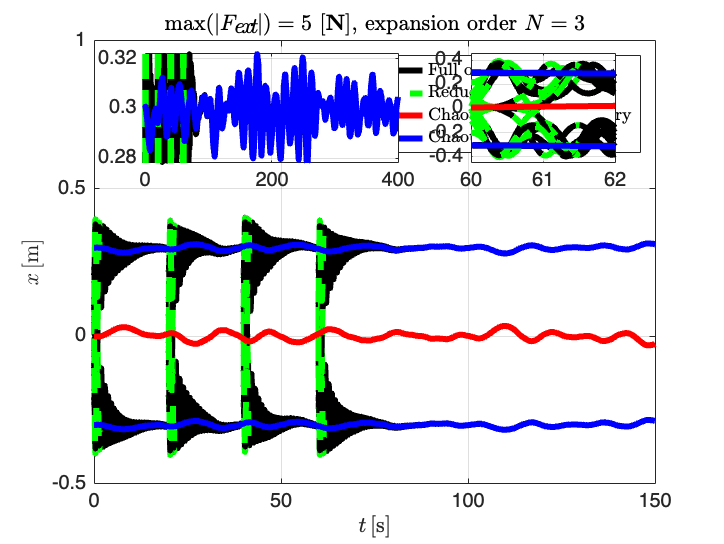

hold(ax1, 'on' );
hold on 
fp3 = plot(ax1,ctspan,Unstable_Solution(:,indexR),'-','LineWidth',3,'color',[1,0,0,0.5]);
hold on 
fp4 = plot(ax1,ctspan,Stable_solution1(:,indexR),'-','LineWidth',3,'color',[0,0,1,0.5]);
hold on 
plot(ax1,ctspan,Stable_solution2(:,indexR),'-','LineWidth',3,'color',[0,0,1,0.5]);
hold on
legend([fp1 fp2 fp3 fp4],'Full order model','Reduced order model','Chaotic anchor trajectory','Chaotic attractors','Interpreter','latex')


hold(ax2, 'on' );
hold on 
plot(ax2,ctspan,Unstable_Solution(:,indexR),'-','LineWidth',3,'color',[1,0,0,0.5]);
hold on 
plot(ax2,ctspan,Stable_solution1(:,indexR),'-','LineWidth',3,'color',[0,0,1,0.5]);
hold on 
plot(ax2,ctspan,Stable_solution2(:,indexR),'-','LineWidth',3,'color',[0,0,1,0.5]);
hold on

% axis([0,750,0.97,1.025])

hold(ax3, 'on' );
hold on 
plot(ax3,ctspan,Unstable_Solution(:,indexR),'-','LineWidth',3,'color',[1,0,0,0.5]);
hold on 
plot(ax3,ctspan,Stable_solution1(:,indexR),'-','LineWidth',3,'color',[0,0,1,0.5]);
hold on 
plot(ax3,ctspan,Stable_solution2(:,indexR),'-','LineWidth',3,'color',[0,0,1,0.5]);
hold on


% axis([0,0.8,-1.2,1.2])


% origUnits = fig.Units;
% fig.Units = fig.PaperUnits;
% fig.PaperSize = fig.Position(3:4);
% fig.Units = origUnits;
% exportgraphics(fig, 'e008xcdot_slow.pdf');

% NMTEavg = sum(NMTET)/6;

% fig1 = figure
% fontsize(fig1, 20, "points")
% set(gcf,'color','w');
% box on
% grid on ;
% ax1 = gca;
% for ind = 1:6
%   plot(ax1,tSP,F_net(ind,:),'-','LineWidth',3,'color',[0 0 0 0.5])
% hold on 
%   
% end    
% hold on 
% plot(ax1,tSP,epsilon*ones(1,max(size(tSP))),'-','LineWidth',3,'color',[1 0 0 0.3])
% 
% save('NMTE0.008_3',"NMTEavg")

% set(fig, 'Units' , 'Inches' );
% pos = get(fig, 'Position' );
% set(fig, 'PaperPositionMode' , 'Auto' , 'PaperUnits' , 'Inches' , 'PaperSize' ,[pos(3), pos(4)])
% set(gcf,'Renderer','painters')
% print(fig, 'rail_x_weak.pdf' , '-dpdf' , '-r300' )
% 
% print(fig, 'rail_force_ratio.pdf' , '-dpdf' , '-r300' )

% set(fig, 'Units' , 'Inches' );
% pos = get(fig, 'Position' );
% set(fig, 'PaperPositionMode' , 'Auto' , 'PaperUnits' , 'Inches' , 'PaperSize' ,[pos(3), pos(4)])
% set(gcf,'Renderer','painters')
% print(fig, 'forcing_weak.pdf' , '-dpdf' , '-r300' )

SSM snapshot

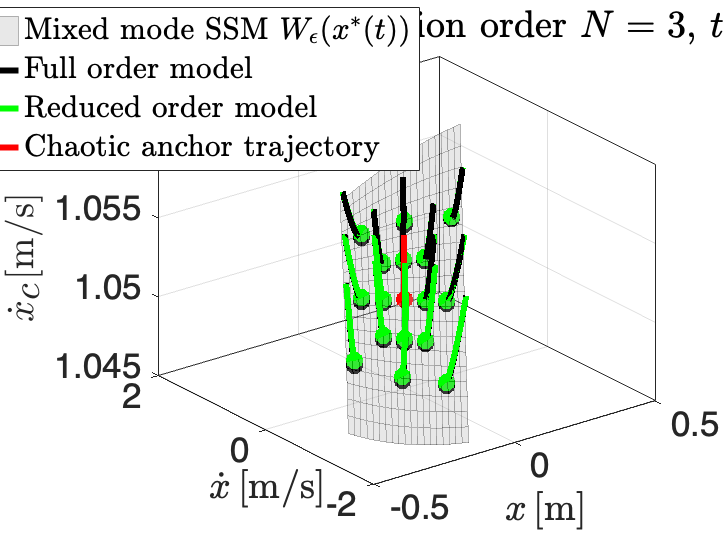

h =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [20×20 double]
           YData: [20×20 double]
           ZData: [20×20 double]
           CData: [20×20 double]

  Show all properties


xl =   Text ($x\,[$m$]$) with properties:

                 String: '$x\,[$m$]$'
               FontSize: 19.8000
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0.1500 0.1500 0.1500]
    HorizontalAlignment: 'left'
               Position: [0.0485 -2.3265 1.0424]
                  Units: 'data'

  Show all properties


hFig = figure('DefaultAxesFontSize',18);                       % Bring up new figure
% imshow('board.tif','Border','tight') % The axes will fill up the entire figure as much as possible without changing aspect ratio.
% hFig.WindowState = 'maximized';
% pause(0.5)
delta = 0.5;
tl =  10;
% tl = 1000
clear movieVector

nssm = 20;
m1 = 1+3;
m2 = 1;
m3 = 1;
spand = 1;
ind = 1;
for j = to(3):to(3) %1:20 %1:20 %1:spand:30 % 1:100:70000%:1200%(max(size(t_sol))-tl)
i = j+0;
     clf
% subplot(2, 2, [1 3])
    
     plotdofs = [1 3 4]; 
   
     x = linspace(-0.6,0.6,nssm);
     y = linspace(-1.4,1.4,nssm);
     [X,Y]=meshgrid(x,y);
    
     Z = X+1i*Y;
     Z = [X(:),Y(:)];
     t_ssm = ones(1,nssm*nssm)*store_Traj{1,1}(j+tl);

%      [ZZ,modalZ,Net_Solz] = compute_SSM_phy(XI_0U,XI_1U,XI_2U,XI_3U,t_ssm,Z(:).',epsilon,SSM_Coeff_A_2,SSM_Coeff_A_1,Valpha,V,A,Force_Lorenz,Dalpha);
%      [ZZ,modalZ] = compute_SSM_phy(XI_hyperbolic_solution,t_ssm,V_new,VI_new,Z.',h030,h300,h120,h210,h111,h201,h021,h012,h102,h500,h050,h410,h140,h230,h320,epsilon);

  [ZZ,modalZ] = compute_SSM_phy(XI_hyperbolic_solution,t_ssm,V_new,VI_new,Z.',h030,h300,h120,h210,h111,h201,h021,h012,h102,epsilon);

%      Z1 = reshape(real(modalZ(plotdofs(1),:)),nssm,nssm);
%      Z2 = reshape(real(modalZ(plotdofs(2),:)),nssm,nssm);
%      Z3 = reshape(imag(modalZ(plotdofs(3),:)),nssm,nssm);

     Z1 = reshape(ZZ(plotdofs(1),:),nssm,nssm);
     Z2 = reshape(ZZ(plotdofs(2),:),nssm,nssm);
     Z3 = reshape(ZZ(plotdofs(3),:),nssm,nssm);



     h = surf(Z1,Z2,Z3)
     h.EdgeColor = [0 0 0];
     h.FaceColor = [.7 .7 .7];
     h.FaceAlpha = 0.3;
     h.EdgeAlpha = 0.3;
     hold on 

%         plot3((store_Traj{1,2}(plotdofs(1),1:2000)),(store_Traj{1,2}(plotdofs(2),1:2000)),(store_Traj{1,2}(plotdofs(3),1:2000)),'-.','LineWidth',1,'Color',[1 0 0 0.5]);
%        hold on 
%       plot3((store_Traj{1,3}(plotdofs(1),1500:2000)),(store_Traj{1,3}(plotdofs(2),1500:2000)),(store_Traj{1,3}(plotdofs(3),1500:2000)),'-.','LineWidth',1,'Color',[0 0 1 0.5]);
%       hold on 
%       plot3((store_Traj{1,4}(plotdofs(1),1500:2000)),(store_Traj{1,4}(plotdofs(2),1500:2000)),(store_Traj{1,4}(plotdofs(3),1500:2000)),'-.','LineWidth',1,'Color',[0 0 1 0.5]);
%        hold on 
%      if (j+tl >= to(1))
%          marker = 2;
%        for nTraj = 1:16
%           
%              ft = plot3((store_Traj{marker,4}(plotdofs(1)+(nTraj-1)*4,j:j+tl)),(store_Traj{marker,4}(plotdofs(2)+(nTraj-1)*4,j:j+tl)),(store_Traj{marker,4}(plotdofs(3)+(nTraj-1)*4,j:j+tl)),'-','LineWidth',3,'Color',[0 0 0 0.5]);
%             hold on 
%           
%             if j+tl <=200
%             rt = plot3((store_Traj{marker,2}(plotdofs(1)+(nTraj-1)*4,j:j+tl)),(store_Traj{marker,2}(plotdofs(2)+(nTraj-1)*4,j:j+tl)),(store_Traj{marker,2}(plotdofs(3)+(nTraj-1)*4,j:j+tl)),'-','LineWidth',3,'Color',[0 1 0 0.5]);
%             hold on 
%              plot3((store_Traj{marker,2}(plotdofs(1)+(nTraj-1)*4,j+tl)),(store_Traj{marker,2}(plotdofs(2)+(nTraj-1)*4,j+tl)),(store_Traj{marker,2}(plotdofs(3)+(nTraj-1)*4,j+tl)),'.','MarkerSize',30,'Color','green');
%             hold on
%             elseif j<=200
%                 end1=200;
%                 rt = plot3((store_Traj{marker,2}(plotdofs(1)+(nTraj-1)*4,j:end1)),(store_Traj{marker,2}(plotdofs(2)+(nTraj-1)*4,j:end1)),(store_Traj{marker,2}(plotdofs(3)+(nTraj-1)*4,j:end1)),'-','LineWidth',3,'Color',[0 1 0 0.5]);
%                 hold on
%             end    
%             
%            
%             plot3((store_Traj{marker,4}(plotdofs(1)+(nTraj-1)*4,j+tl)),(store_Traj{marker,4}(plotdofs(2)+(nTraj-1)*4,j+tl)),(store_Traj{marker,4}(plotdofs(3)+(nTraj-1)*4,j+tl)),'.','MarkerSize',30,'Color','black');
%             hold on
% %             plot3(store_Traj{marker,2}(j+tl,plotdofs(1)+(nTraj-1)*4),store_Traj{marker,2}(j+tl,plotdofs(2)+(nTraj-1)*4),store_Traj{marker,2}(j+tl,plotdofs(3)+(nTraj-1)*4),'.','MarkerSize',30,'Color','green');
% %             hold on
%        end  
%      end  
%      if   (j+tl >= to(2))
%            marker = 3;
% 
%             for nTraj = 1:16
%           
%              ft = plot3((store_Traj{marker,4}(plotdofs(1)+(nTraj-1)*4,m1:m1+tl)),(store_Traj{marker,4}(plotdofs(2)+(nTraj-1)*4,m1:m1+tl)),(store_Traj{marker,4}(plotdofs(3)+(nTraj-1)*4,m1:m1+tl)),'-','LineWidth',3,'Color',[0 0 0 0.5]);
% 
%             if m1+tl <=26
%             rt = plot3((store_Traj{marker,2}(plotdofs(1)+(nTraj-1)*4,m1:m1+tl)),(store_Traj{marker,2}(plotdofs(2)+(nTraj-1)*4,m1:m1+tl)),(store_Traj{marker,2}(plotdofs(3)+(nTraj-1)*4,m1:m1+tl)),'-','LineWidth',3,'Color',[0 1 0 0.5]);
%             hold on 
%              plot3((store_Traj{marker,2}(plotdofs(1)+(nTraj-1)*4,m1+tl)),(store_Traj{marker,2}(plotdofs(2)+(nTraj-1)*4,m1+tl)),(store_Traj{marker,2}(plotdofs(3)+(nTraj-1)*4,m1+tl)),'.','MarkerSize',30,'Color','green');
%             hold on
%             elseif m1<=26
%                 end1=26;
%                 rt = plot3((store_Traj{marker,2}(plotdofs(1)+(nTraj-1)*4,m1:end1)),(store_Traj{marker,2}(plotdofs(2)+(nTraj-1)*4,m1:end1)),(store_Traj{marker,2}(plotdofs(3)+(nTraj-1)*4,m1:end1)),'-','LineWidth',3,'Color',[0 1 0 0.5]);
%                 hold on
%             end 
% 
%             plot3((store_Traj{marker,4}(plotdofs(1)+(nTraj-1)*4,m1+tl)),(store_Traj{marker,4}(plotdofs(2)+(nTraj-1)*4,m1+tl)),(store_Traj{marker,4}(plotdofs(3)+(nTraj-1)*4,m1+tl)),'.','MarkerSize',30,'Color','black');
%             hold on
% 
% %             plot3(store_Traj{marker,2}(j+tl,plotdofs(1)+(nTraj-1)*4),store_Traj{marker,2}(j+tl,plotdofs(2)+(nTraj-1)*4),store_Traj{marker,2}(j+tl,plotdofs(3)+(nTraj-1)*4),'.','MarkerSize',30,'Color','green');
% %             hold on
%            end 
%       
%        m1 = m1 + spand;
%      end   
     if     (j+tl >= to(3))
          marker = 4;
          for nTraj = 1:16
          
             ft = plot3((store_Traj{marker,4}(plotdofs(1)+(nTraj-1)*4,m2:m2+tl)),(store_Traj{marker,4}(plotdofs(2)+(nTraj-1)*4,m2:m2+tl)),(store_Traj{marker,4}(plotdofs(3)+(nTraj-1)*4,m2:m2+tl)),'-','LineWidth',3,'Color',[0 0 0 0.5]);
            hold on 
             if m2+tl <=200
            rt = plot3((store_Traj{marker,2}(plotdofs(1)+(nTraj-1)*4,m2:m2+tl)),(store_Traj{marker,2}(plotdofs(2)+(nTraj-1)*4,m2:m2+tl)),(store_Traj{marker,2}(plotdofs(3)+(nTraj-1)*4,m2:m2+tl)),'-','LineWidth',3,'Color',[0 1 0 0.5]);
            hold on 
             plot3((store_Traj{marker,2}(plotdofs(1)+(nTraj-1)*4,m2+tl)),(store_Traj{marker,2}(plotdofs(2)+(nTraj-1)*4,m2+tl)),(store_Traj{marker,2}(plotdofs(3)+(nTraj-1)*4,m2+tl)),'.','MarkerSize',30,'Color','green');
            hold on
            elseif m2<=200
                end1=200;
                rt = plot3((store_Traj{marker,2}(plotdofs(1)+(nTraj-1)*4,m2:end1)),(store_Traj{marker,2}(plotdofs(2)+(nTraj-1)*4,m2:end1)),(store_Traj{marker,2}(plotdofs(3)+(nTraj-1)*4,m2:end1)),'-','LineWidth',3,'Color',[0 1 0 0.5]);
                hold on
            end

            plot3((store_Traj{marker,4}(plotdofs(1)+(nTraj-1)*4,m2+tl)),(store_Traj{marker,4}(plotdofs(2)+(nTraj-1)*4,m2+tl)),(store_Traj{marker,4}(plotdofs(3)+(nTraj-1)*4,m2+tl)),'.','MarkerSize',30,'Color','black');
            hold on

%             plot3(store_Traj{marker,2}(j+tl,plotdofs(1)+(nTraj-1)*4),store_Traj{marker,2}(j+tl,plotdofs(2)+(nTraj-1)*4),store_Traj{marker,2}(j+tl,plotdofs(3)+(nTraj-1)*4),'.','MarkerSize',30,'Color','green');
%             hold on
           end 
        
       m2 = m2 + spand;
     end
%      if (j+tl >= to(4))
%           marker = 5;
%        for nTraj = 1:16
%           
%             ft = plot3((store_Traj{marker,4}(plotdofs(1)+(nTraj-1)*4,m3:m3+tl)),(store_Traj{marker,4}(plotdofs(2)+(nTraj-1)*4,m3:m3+tl)),(store_Traj{marker,4}(plotdofs(3)+(nTraj-1)*4,m3:m3+tl)),'-','LineWidth',3,'Color',[0 0 0 0.5]);
%             hold on 
%              if m3+tl <=200
%             rt = plot3((store_Traj{marker,2}(plotdofs(1)+(nTraj-1)*4,m3:m3+tl)),(store_Traj{marker,2}(plotdofs(2)+(nTraj-1)*4,m3:m3+tl)),(store_Traj{marker,2}(plotdofs(3)+(nTraj-1)*4,m3:m3+tl)),'-','LineWidth',3,'Color',[0 1 0 0.5]);
%             hold on 
%              plot3((store_Traj{marker,2}(plotdofs(1)+(nTraj-1)*4,m3+tl)),(store_Traj{marker,2}(plotdofs(2)+(nTraj-1)*4,m3+tl)),(store_Traj{marker,2}(plotdofs(3)+(nTraj-1)*4,m3+tl)),'.','MarkerSize',30,'Color','green');
%             hold on
%             elseif m3<=200
%                 end1=200;
%                 rt = plot3((store_Traj{marker,2}(plotdofs(1)+(nTraj-1)*4,m3:end1)),(store_Traj{marker,2}(plotdofs(2)+(nTraj-1)*4,m3:end1)),(store_Traj{marker,2}(plotdofs(3)+(nTraj-1)*4,m3:end1)),'-','LineWidth',3,'Color',[0 1 0 0.5]);
%                 hold on
%             end
% 
%             plot3((store_Traj{marker,4}(plotdofs(1)+(nTraj-1)*4,m3+tl)),(store_Traj{marker,4}(plotdofs(2)+(nTraj-1)*4,m3+tl)),(store_Traj{marker,4}(plotdofs(3)+(nTraj-1)*4,m3+tl)),'.','MarkerSize',30,'Color','black');
%             hold on
% %             plot3(store_Traj{marker,2}(j+tl,plotdofs(1)+(nTraj-1)*4),store_Traj{marker,2}(j+tl,plotdofs(2)+(nTraj-1)*4),store_Traj{marker,2}(j+tl,plotdofs(3)+(nTraj-1)*4),'.','MarkerSize',30,'Color','green');
% %             hold on
%         end  
%         
%        m3 = m3 + spand;
% 
%      end 
     hold on
      unst = plot3((store_Traj{1,2}(plotdofs(1),j:j+tl)),(store_Traj{1,2}(plotdofs(2),j:j+tl)),(store_Traj{1,2}(plotdofs(3),j:j+tl)),'-','LineWidth',3,'Color',[1 0 0]);
      hold on 
%       st = plot3((store_Traj{1,3}(plotdofs(1),j:j+tl)),(store_Traj{1,3}(plotdofs(2),j:j+tl)),(store_Traj{1,3}(plotdofs(3),j:j+tl)),'-','LineWidth',3,'Color',[0 0 1]);
%       hold on 
%       plot3((store_Traj{1,4}(plotdofs(1),j:j+tl)),(store_Traj{1,4}(plotdofs(2),j:j+tl)),(store_Traj{1,4}(plotdofs(3),j:j+tl)),'-','LineWidth',3,'Color',[0 0 1]);
%       
%       hold on
       plot3((store_Traj{1,2}(plotdofs(1),j+tl)),(store_Traj{1,2}(plotdofs(2),j+tl)),(store_Traj{1,2}(plotdofs(3),j+tl)),'.','MarkerSize',30,'Color','red');
      hold on 
%       plot3((store_Traj{1,3}(plotdofs(1),j+tl)),(store_Traj{1,3}(plotdofs(2),j+tl)),(store_Traj{1,3}(plotdofs(3),j+tl)),'.','MarkerSize',30,'Color',[0,0,1]);
%       hold on 
%       plot3((store_Traj{1,4}(plotdofs(1),j+tl)),(store_Traj{1,4}(plotdofs(2),j+tl)),(store_Traj{1,4}(plotdofs(3),j+tl)),'.','MarkerSize',30,'Color',[0,0,1]);
      
      
    xl =xlabel('$x\,[$m$]$','Interpreter','latex');

%     xl.Position = [0.0793 -2.4921+0.2 -0.1372]
%      xl.Position = [0.0793 -2.2921 -0.0072];

      xl.Position = [0.0485 -2.3265 1.0424]

% xl.Position = [0.1111 -1.0188+0.05 -1.9472+0.05]
    xl.HorizontalAlignment = 'center';
     yl =ylabel('$\dot{x}\,[$m/s$]$','Interpreter','latex');
%      yl.Position = [-0.5002 0.5250 -0.1382];
%       yl.Position = [-0.5002 0.5250 -0.0082];
       yl.Position = [-0.4539 +0.2 1.0421];


    yl.HorizontalAlignment = 'center';
     zl = zlabel('$\dot{x}_c \,[$m/s$]$','Interpreter','latex');
     title_string = strcat('max$(|F_{ext}|) = ',num2str(epsilon*(M+m)),'$ [$\mathbf{N}$], expansion order $N = 3$, $t =',num2str(round(t_ssm(1,1),2),'%4.2f'),'$');
       title(title_string,'Interpreter','latex')
%          legend('SSM - $W_{\epsilon}(x_{\epsilon}(\alpha))$ $O(\epsilon^{k_1} \mathbf{u}^{\mathbf{k}_2}, k_1 + |k_2| = 3)$','$O(\epsilon^3)$ anchor trajectory','Full order model','Reduced order model','$O(\epsilon^3)$ anchor trajectory [$x_{\epsilon}(\alpha = \epsilon t)$]','Interpreter','latex','location','northwest')
%   rt = plot3(0,0,0,'-','LineWidth',3,'Color',[0 1 0 0.5]);
%             hold on 
% l = legend([h ft rt unst st],'SSM - $W_{\epsilon}(x^{*}(t))$ $O(\epsilon^{k_1} \mathbf{u}^{\mathbf{k}_2}, k_1 + |k_2| = 3)$','Full order model','Reduced order model','Anchor trajectory','Stable solutions','Interpreter','latex','location','northwest');
% l.Position = [0.1353 0.7847 0.2358 0.1311];
   l = legend([h ft rt unst],'Mixed mode SSM $W_{\epsilon}(x^{*}(t))$','Full order model','Reduced order model','Chaotic anchor trajectory','Interpreter','latex','location','northwest');
l.Position = [0.0411 0.7363 0.4284 0.1982];

%        legend([h ft unst st],'SSM - $W_{\epsilon}(x_{\epsilon}(\alpha))$ $O(\epsilon^{k_1} \mathbf{u}^{\mathbf{k}_2}, k_1 + |k_2| = 3)$','Full order model','$O(\epsilon^3)$ anchor trajectory [$x_{\epsilon}(\alpha = \epsilon t)$]','$O(\epsilon^3)$ stable solutions','Interpreter','latex','location','northwest')

%     string = strcat('\alpha = ',num2str(round(epsilon*t_sol(j+tl),2),'%4.2f' ),', \epsilon = 0.008');
%     if (round(epsilon*t_sol(j+tl),2)) >=1
%      string = strcat('{\color{blue}\alpha = ',num2str(round(epsilon*t_sol(j+tl),2),'%4.2f' ),',}\epsilon = 0.008');
%      title(string);
%     else
%      title(string);
%     end   
%        axis([-0.2,0.2,-1,1,-2*10^-3,18*10^-3])
%    view(-34,6)


    grid on
    box on
%             daspect([1,1,1])
%    axis([-0.4,0.4,-2,2,-0.1,0.24])
set(gcf,'color','white')
    figssm = gcf;

movieVector(ind) = getframe(hFig);
    
    ind = ind +1;

end


% myWriter = VideoWriter('SSM_Rail_solutions_weak_slow','MPEG-4');
% myWriter.FrameRate = 20;
% 
% open(myWriter);
% writeVideo(myWriter,movieVector);
% close(myWriter);

% 
% 
% for indj = 1:732
% writeVideo(myWriter,movieVector(indj));
% end
% 
% close(myWriter);

% set(hFig, 'Units' , 'Inches' );
% pos = get(hFig, 'Position' );
% set(hFig, 'PaperPositionMode' , 'Auto' , 'PaperUnits' , 'Inches' , 'PaperSize' ,[pos(3), pos(4)])
% set(gcf,'Renderer','painters')
% print(hFig, 'ssm_rail_weak_snap2.pdf' , '-dpdf')



For $\epsilon = 1$ we compute the ratio of the trajectory averaged external and internal forces of the system.

if flag==1
c = 0.3;
k = 1;
a = 0.3;
g = 9.8;
m = 1;
M = 4;
cf = 0.3;
scale = 5*a^3;%2*a^3;
Sc = scale;
K = [-4*a^2*m*g/scale+k*m^2/(m+M)^2, -k*m/(m+M);-k*m/(m+M),k];
C = [cf+c*m^2/(m+M)^2,-c*m/(m+M);-c*m/(m+M),c];
MT = [m*M/(m+M),0;0,m+M];
F_I_net = [];

fig = figure
NMTET = [];
nssm = 30;
x = linspace(-1,1,nssm);
[X,Y]=meshgrid(x);
Ratio_Net = zeros(nssm,nssm);
Net1 = zeros(nssm,nssm);
Net2 = zeros(nssm,nssm);

for ind = 1:nssm
    for indk = 1:nssm
    epsilon = 1;

    % ROM_ODE_ns =@(t,zk) rom_temp_model_noscale(t,zk,l1,gamma,epsilon,xi_sol1,xi_sol3,h030,h300,h210,h120,H_Coeff1,f030,f300,f210,f120,F_Coeff1);
    ctspan = linspace(0,500,8000);
    u0 = [X(ind,indk);Y(ind,indk)];
    [y0,modal0] = compute_SSM_phy(XI_hyperbolic_solution,0,V_new,VI_new,u0,h030,h300,h120,h210,h111,h201,h021,h012,h102,epsilon);
    GH = @(t,y) Full_Order_Model_PM_vec(t,y,Force_Lorenz,0,c,k,a,g,m,M,cf,Sc);
    tic
    IC = y0;
    [tSP,Full_Traj] = ode45(GH,ctspan,IC);
    toc


    y = Full_Traj.';
    F_an = (abs((m+M)*epsilon*Force_Lorenz(tSP))).';

    F_spring = K*[y(1,:);y(2,:)];
    F_damper = C*[y(3,:);y(4,:)];
    F_nonlinear = [4*g*m*y(1,:).^3/scale + 16*m*a^4*y(1,:).*y(3,:).^2/scale^2;0*y(1,:)];
    F_total = F_spring + F_damper + F_nonlinear;
    F_net = sqrt(sum(F_total.^2));
    F_I_net = [F_I_net;max(F_net)];
    Net1(ind,indk) = trapz(tSP,F_an)/(max(tSP));
    Net2(ind,indk) = (trapz(tSP,F_net)/(max(tSP)));

    Ratio_Net(ind,indk) = trapz(tSP,F_an)/(max(tSP))./(trapz(tSP,F_net)/(max(tSP)));


    end
end
bp = mean( Net1(:))./mean( Net2(:));
NMTEavg = sum(NMTET)/6;
factor = epsilon/max(F_I_net);

save('Mean_force_ratio.mat','bp');
save('XYR.mat','Ratio_Net','X','Y');

end

load('XYR.mat','Ratio_Net','X','Y');

fig = figure

fig =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 460 560 420]
       Units: 'pixels'

  Show all properties


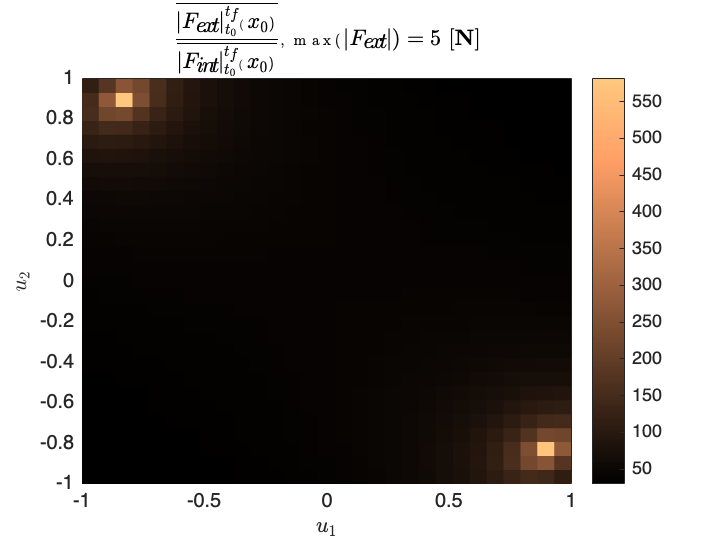

P = pcolor(X,Y,Ratio_Net);
P.EdgeColor = 'none';
colormap copper
colorbar 
xlabel('$u_1$','Interpreter','latex');
ylabel('$u_2$','Interpreter','latex');

title_string = strcat('$\displaystyle \frac{\overline{|F_{ext}|_{t_0}^{t_f}(x_0)}}{\overline{|F_{int}|_{t_0}^{t_f}(x_0)}}$, max$(|F_{ext}|) = ',num2str(epsilon*(M+m)),'$ [$\mathbf{N}$]');


title(title_string,'Interpreter','latex')

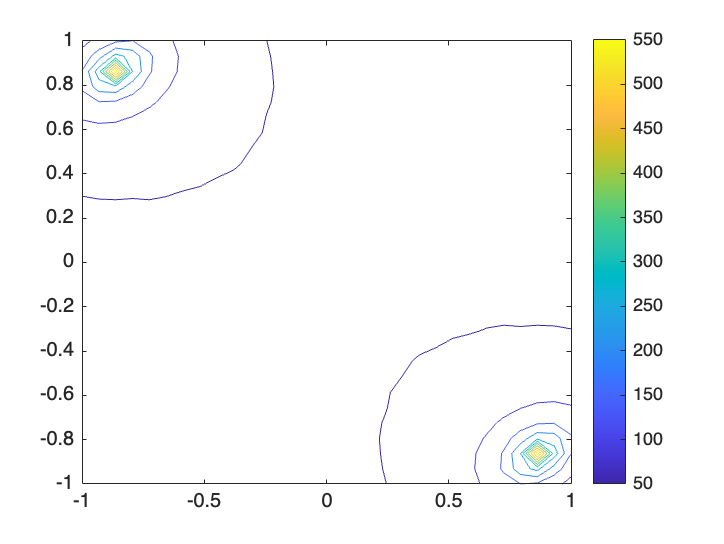


figure 
contour(X,Y,Ratio_Net)
colorbar


load('Mean_force_ratio.mat','bp');
disp(['Mean ratio of external and internal forces = ',num2str(bp)]);

Mean ratio of external and internal forces = 44.5714
